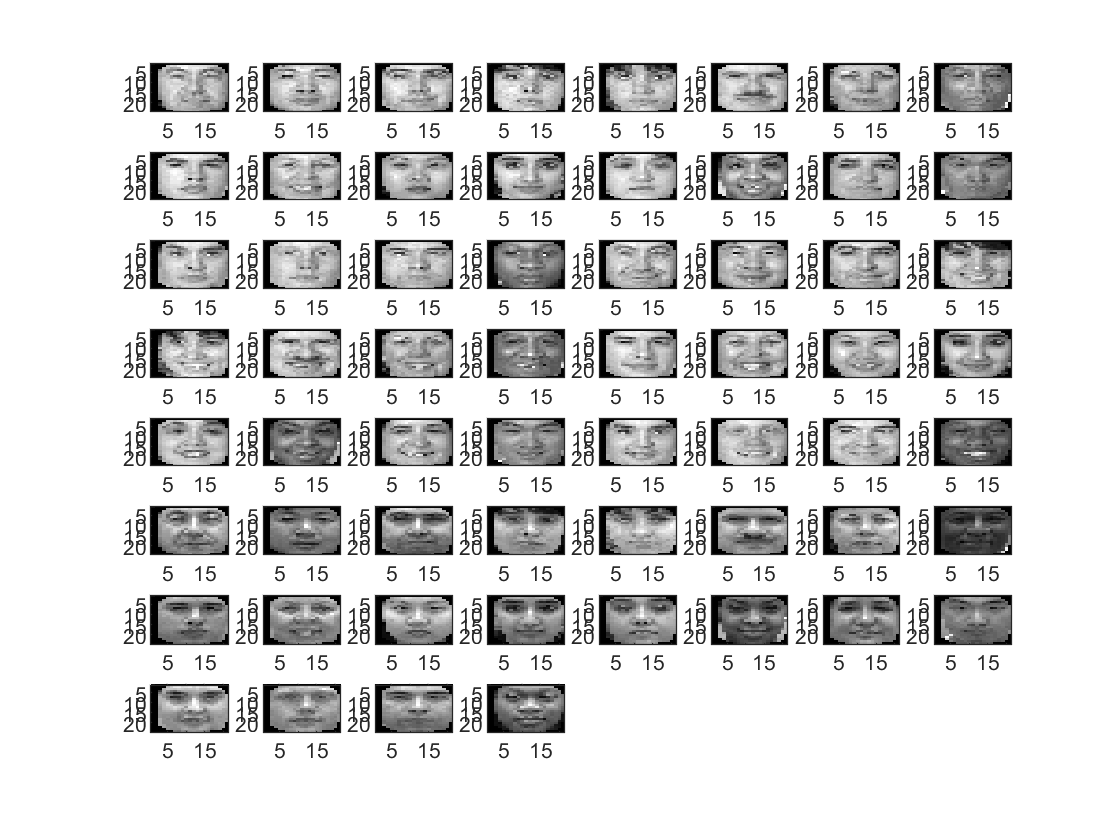

faces = load('data.mat');
[fn, fs, fi] = deal(faces.face(:,:,1:3:end), faces.face(:,:,2:3:end),faces.face(:,:,3:3:end));
figure, clf;
colormap 'gray';
for i=1:20
    subplot(8,8,i);
    imagesc(fn(:,:,i)); 
    subplot(8,8,i+20);
    imagesc(fs(:,:,i));
    subplot(8,8,i+40);
    imagesc(fi(:,:,i));
end

## Fisher Discriminant Analysis

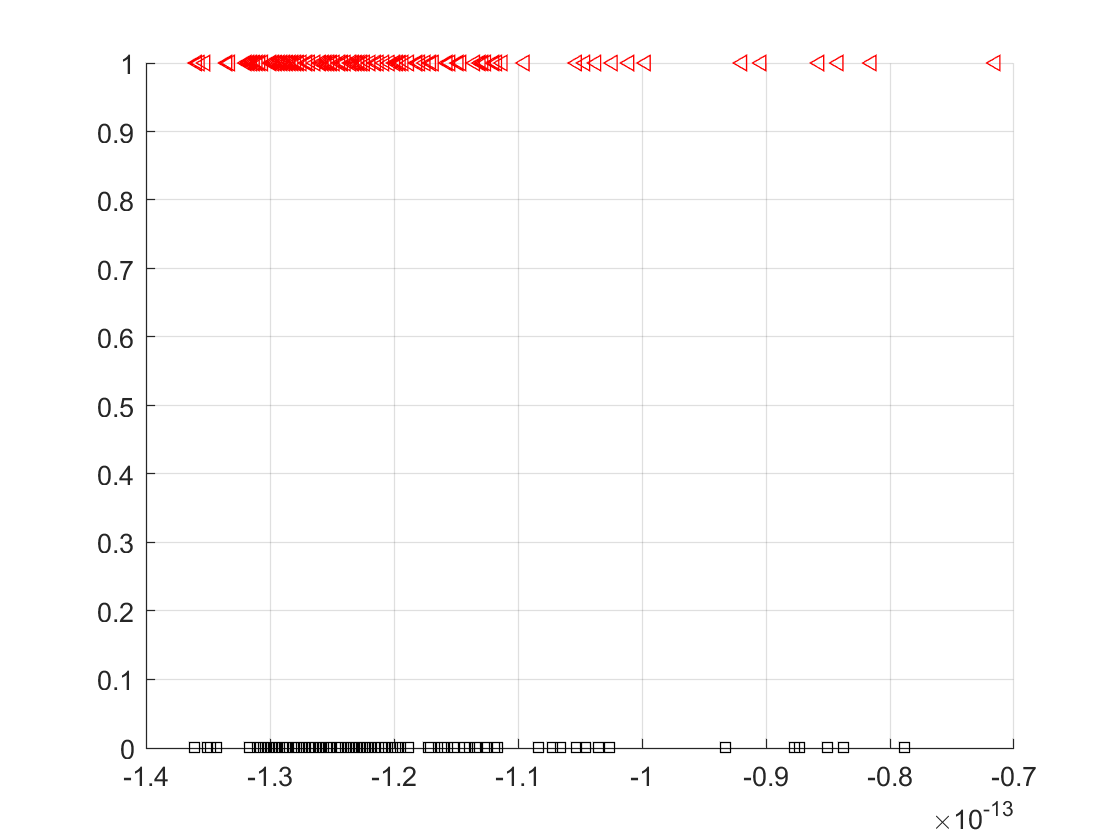

tst_trn_spl = 0.60;
[d1, d2, n] = deal(size(fn,1), size(fn,2), size(fn,3)*tst_trn_spl);
[X1 X2] = deal(zeros(n,d1*d2));
for i=1:n
    tmp1=fn(:,:,i); tmp2=fs(:,:,i);
    X1(i,:)=tmp1(:)'; X2(i,:)=tmp2(:)'; 
end
mn = mean(X1,1); ms=mean(X2,1);
Xc1 = X1-ones(n,1)*mn; Xc2=X2-ones(n,1)*ms; %centered the data
S1 = Xc1'*Xc1; S2=Xc2'*Xc2;
Sw = S1 + S2;
Sb = (mn - ms)'*(mn - ms);
[W, lam0] = eig(Sb,Sw);
lam0 = sort(lam0,'descend'); [lams, idx] = sort(lam0,2,'descend');
Ws = W(:,idx);
w = Ws(:,1);
X = [X1;X2];
D1= 1:n;
D2=n+1:2*n;
y=X*w;
figure; hold on; grid;
plot(y(D1),zeros(n,1),'s','color','none','MarkerEdgeColor','k','MarkerSize',5);
plot(y(D2),ones(n,1),'<','color','none','MarkerEdgeColor','r','MarkerSize',5);

## Attempt to map the data with reduced dimension using PCA

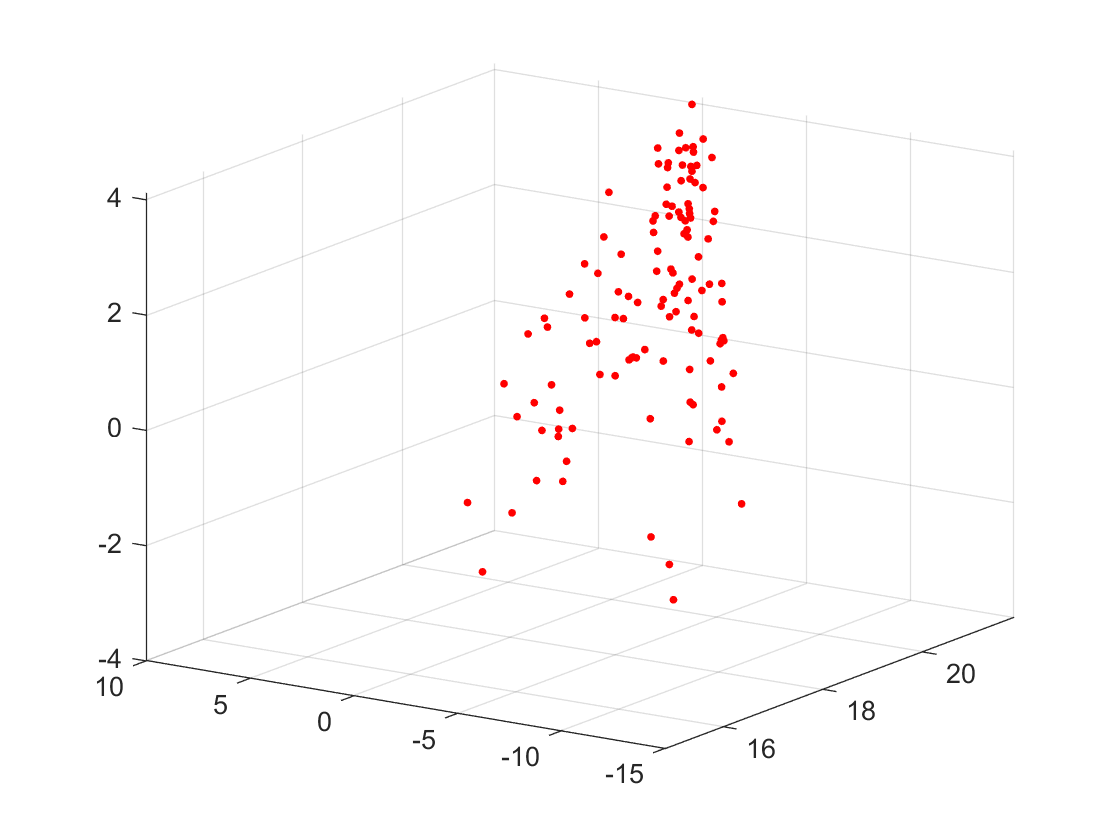

[U, Sigma, V] = svd(X','econ');
nPCA = 20; %Projecting to 20 dimensions
Yb = X*U(:,1:nPCA);
figure; hold on; grid;
plot3(Yb(D1,1),Yb(D1,2),Yb(D1,3),'.r', ...%Yb(D2,1),Yb(D2,2),Yb(D2,3),'.k',% 
'MarkerSize',10);
view([-56.2 18.5])

## Use Bayesian classifier

Yb1 = Yb(D1,:); Yb2 = Yb(D2,:);
mb1 = mean(Yb1); mb2 = mean(Yb2);
norm(mb1 - mb2)

ans = 3.3180

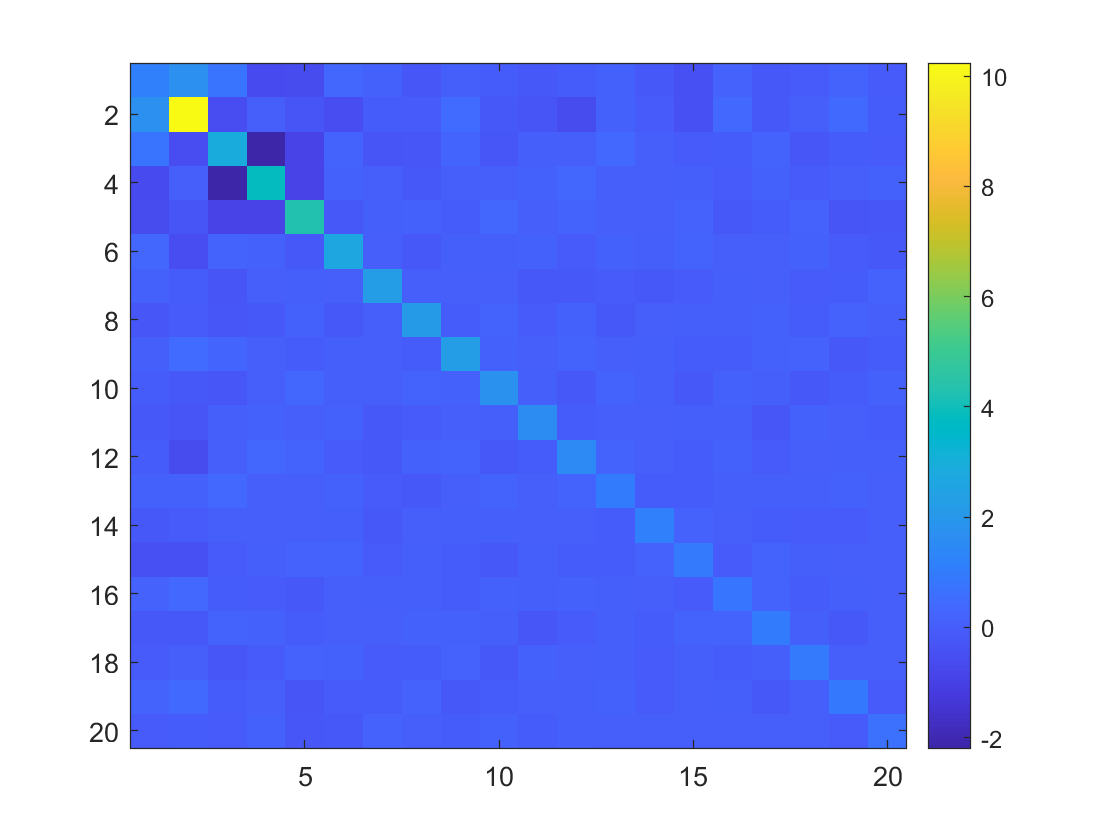

Yb1c = Yb1 - ones(n,1)*mb1;
Yb2c = Yb2 - ones(n,1)*mb2;
Sb1 = Yb1c'*Yb1c/(n-1);
Sb2 = Yb2c'*Yb2c/(n-1);
figure; imagesc(Sb1);colorbar;

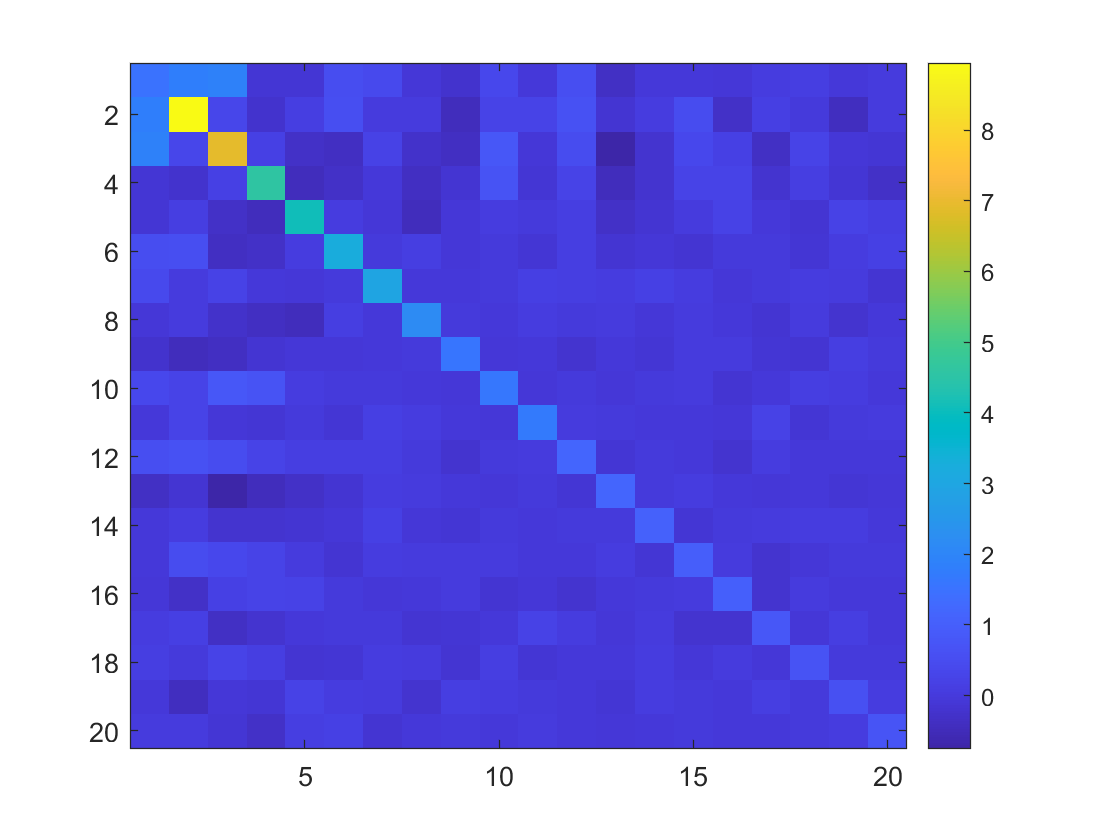

figure;imagesc(Sb2);colorbar;

iSb1 = inv(Sb1); iSb2 = inv(Sb2);
Sb1d = det(Sb1); Sb2d = det(Sb2);
f1 = @(x)(2*pi)^(-nPCA/0.5)*(1/(Sb1d^0.5))*exp((-0.5)*(x-mb1')'*iSb1*(x-mb1'));
f2 = @(x)(2*pi)^(-nPCA/0.5)*(1/(Sb2d^0.5))*exp((-0.5)*(x-mb2')'*iSb2*(x-mb2'));
label = zeros(size(fn,3)*0.3,1);
for i=size(fn,3)*tst_trn_spl+1:size(fn,3)
    tmp1=fn(:,:,i);
    xt = tmp1(:)'*U(:,1:nPCA);
    p1 = f1(xt'); 
    p2 = f2(xt');
    if p1 < p2
        label(i) = 2;
    else
        label(i) = 1;
    end
    %fprintf("p1=%50.50f, p2=%50.50f\n",p1,p2);
end
fn_predict = find(label == 1);
fs_predict = find(label == 2);
fprintf('Testing Neutral faces: positive=%d, negative=%d, Error=%f\n',...
    size(fn_predict,1), size(fs_predict,1),size(fs_predict,1)/(size(fn_predict,1)+size(fs_predict,1)));

Testing Neutral faces: positive=76, negative=4, Error=0.050000


for i=size(fs,3)*tst_trn_spl+1:size(fs,3)
    tmp1=fs(:,:,i);
    xt = tmp1(:)'*U(:,1:nPCA);
    p1 = f1(xt'); 
    p2 = f2(xt');
    if p1 < p2
        label(i) = 2;
    else
        label(i) = 1;
    end
    %fprintf("p1=%50.50f, p2=%50.50f\n",p1,p2);
end
fn_predict = find(label == 1);
fs_predict = find(label == 2);
fprintf('Testing Smily faces: positive=%d, negative=%d, Error=%f\n',...
    size(fs_predict,1), size(fn_predict,1),size(fn_predict,1)/(size(fn_predict,1)+size(fs_predict,1)));

Testing Smily faces: positive=67, negative=13, Error=0.162500
